# **Controller Tuning **

**Combined Braking or Accelerating **

## for

# `longitudinal Vehicle Motion Control from gain scheduled LTI systems modeled on more complex dynamics.`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`8/21/23`

` Ohio State University`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

clc; clear; close all;

% Controller and vehicle Plant Info
load('longitudinalModelData80923.mat')
longModData = longitudinalModelData80823

longModData = 107×11 table
     Vs     Tm_Tb       K          T          rmse       time     avg_acc       dX        Ve      Tm     Tb
    ____    _____    ________    ______    __________    ____    _________    ______    ______    ___    __

       0       0      0.52277    198.47      0.013211      0             0         0         0      0    0 
    0.01      55      0.53809    111.13      0.010918    600      0.049325     14695    29.605     55    0 
    0.01      80      0.48331    85.937     0.0091168    600      0.064442     20125    38.675     80    0 
    0.01     105      0.43781    71.785     0.0078491    6

load('accControllersData81623.mat')
accC = accControllersData81623;
load('brakeControllersData81623.mat')
brakeC = brakeControllersData81623;
controllers = [accC;brakeC]

controllers = 10×6 table
     Vs     Tm_Tb    Kp      Ki       Kd       N   
    ____    _____    ___    _____    ____    ______

    0.01     170     4.5    0.111    14.7    0.0646
      44     170      10      0.3    3.75    0.0575
      44      40     -10    -0.15     -40      0.04
    0.01      40      12     0.15      60      0.04
      22      40       7    0.125       1      0.07
      22     170      15      0.3       1      0.07
     5.1      -6       1     0.05       8      0.06
     5.1    -290      90       17      15       0.1
    44.9      -6     0.7    0.007    0.55      0.03
    44.9    -290      20      0.8       2       0.1


# Interpolate Plant and PID parameters for an interior Velocity and Torque

vstarts = 0.01:2:46;
torques = -310:20:195;

% Create matrices that represent all combinations of the elements
[V, T] = ndgrid(vstarts, torques);

% Reshape and concatenate into a single matrix
tests = [V(:), T(:)];

% Number of test conditions
nTests = size(tests, 1);

% Create an array to store test conditions that cause errors
error_conditions = [];
non_error_conditions = [];

% Iterate through each test condition
for i = 1:nTests
    % Set the variables for the current test condition
    vstart = tests(i, 1);
    torque = tests(i, 2);

    % Calculate K, T, Kp, Ki, Kd, and N
    % Use try-catch to handle errors
    try
        % Choose Controllers for braking or for acceleration
        if torque > 0 
            controllersNow = accC;
            Ref = vstart+1;
        end 
        if torque < 0 
            controllersNow = brakeC;
            Ref = vstart-1;
        end 
        % Calculate K, T, Kp, Ki, Kd, and N
        K = bilinearInterpolation(vstart,torque,longModData.K,longModData.Vs,longModData.Tm_Tb);
        T = bilinearInterpolation(vstart,torque,longModData.T,longModData.Vs,longModData.Tm_Tb);
        Kp = bilinearInterpolation(vstart,torque,controllersNow.Kp,controllersNow.Vs,controllersNow.Tm_Tb);
        Ki = bilinearInterpolation(vstart,torque,controllersNow.Ki,controllersNow.Vs,controllersNow.Tm_Tb);
        Kd = bilinearInterpolation(vstart,torque,controllersNow.Kd,controllersNow.Vs,controllersNow.Tm_Tb);
        N = bilinearInterpolation(vstart,torque,controllersNow.N,controllersNow.Vs,controllersNow.Tm_Tb);
        non_error_conditions = [non_error_conditions; [vstart, torque, Ref,K,T,Kp,Ki,Kd,N]];

    catch exception
        % Record test condition that caused error
        error_conditions = [error_conditions; [vstart, torque, Ref]];
        % Display a message or save the error message if needed
        %disp(['Error in test condition [', num2str(start), ', ', num2str(torque), ', ', num2str(Ref), ']: ', exception.message]);
    end
end 

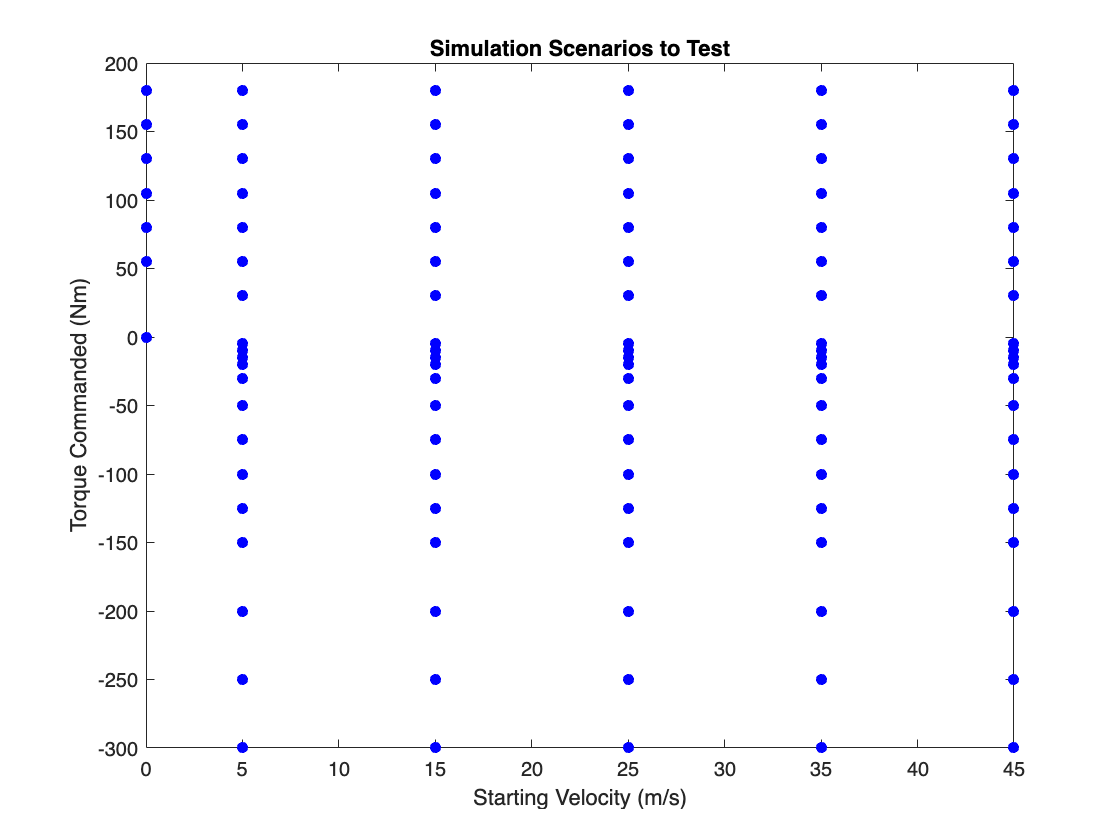

figure
plotDesignPoint(controllers.Vs,controllers.Tm_Tb,longModData)

hold on, plot(tests(:, 1),tests(:, 2),'go','MarkerFaceColor','g','MarkerSize',2) % All tests
plot(error_conditions(:,1),error_conditions(:,2),'ro','MarkerFaceColor','r','MarkerSize',2) % Errors

# Testing Step Responses

vstarts = 0.01:2:46;
torques = -310:20:210;

% Create matrices that represent all combinations of the elements
[V, T] = ndgrid(vstarts, torques);

% Reshape and concatenate into a single matrix
tests = [V(:), T(:)];

% Number of test conditions
nTests = size(tests, 1);

% Create an array to store test conditions that cause errors
error_conditions = [];
non_error_conditions = [];

% Iterate through each test condition
for i = 1:nTests
    % Set the variables for the current test condition
    vstart = tests(i, 1);
    torque = tests(i, 2);

    % Calculate K, T, Kp, Ki, Kd, and N
    % Use try-catch to handle errors
    try
        % Choose Controllers for braking or for acceleration
        if torque > 0 
            controllersNow = accC;
            Ref = vstart+1;
                    opt = RespConfig;
                    opt.InputOffset = 0;
                    opt.Amplitude = 1;
        end 
        if torque < 0 
            controllersNow = brakeC;
            Ref = vstart-1;
                    opt = RespConfig;
                    opt.InputOffset = 0;
                    opt.Amplitude = -1;
        end 
        % Calculate K, T, Kp, Ki, Kd, and N
        K = bilinearInterpolation(vstart,torque,longModData.K,longModData.Vs,longModData.Tm_Tb);
        T = bilinearInterpolation(vstart,torque,longModData.T,longModData.Vs,longModData.Tm_Tb);
        Kp = bilinearInterpolation(vstart,torque,controllersNow.Kp,controllersNow.Vs,controllersNow.Tm_Tb);
        Ki = bilinearInterpolation(vstart,torque,controllersNow.Ki,controllersNow.Vs,controllersNow.Tm_Tb);
        Kd = bilinearInterpolation(vstart,torque,controllersNow.Kd,controllersNow.Vs,controllersNow.Tm_Tb);
        N = bilinearInterpolation(vstart,torque,controllersNow.N,controllersNow.Vs,controllersNow.Tm_Tb);

        %SIMULATE
        % 1 mps faster Simulation 
        s = tf('s');
        sys = K/(T*s+1);
        C = pid(Kp,Ki,Kd,N);
        H = feedback(50*C*sys,1);

        [h,g] = step(H,opt);
        speed = vstart+h;
        time = g;
        Vend = speed(length(speed));


        % Find time and speed when the difference is 30% or less of the reference
        diffValue = abs(speed - Ref);

        % Finding the index where the difference is 30% or less of the reference
        index_30_percent_or_less = find(diffValue <= 0.3, 1, 'first');
        
        time_70_percent = time(index_30_percent_or_less);
        speed_70_percent = speed(index_30_percent_or_less);

        t_end = time_70_percent;

        % Compute the error up to 70% peak time
        error = 1 - h(1:find(time == time_70_percent));
        
        % Compute controller's output using this error
        controller_output = mean(lsim(C, error, g(1:find(time == time_70_percent))));
        %controller_output = 1;

        non_error_conditions = [non_error_conditions; [vstart, torque, Ref,K,T,Kp,Ki,Kd,N,time_70_percent,speed_70_percent,controller_output]];

    catch exception
        % Record test condition that caused error
        error_conditions = [error_conditions; [vstart, torque, Ref]];
        % Display a message or save the error message if needed
        %disp(['Error in test condition [', num2str(start), ', ', num2str(torque), ', ', num2str(Ref), ']: ', exception.message]);
    end
end 

# Test Individual Result

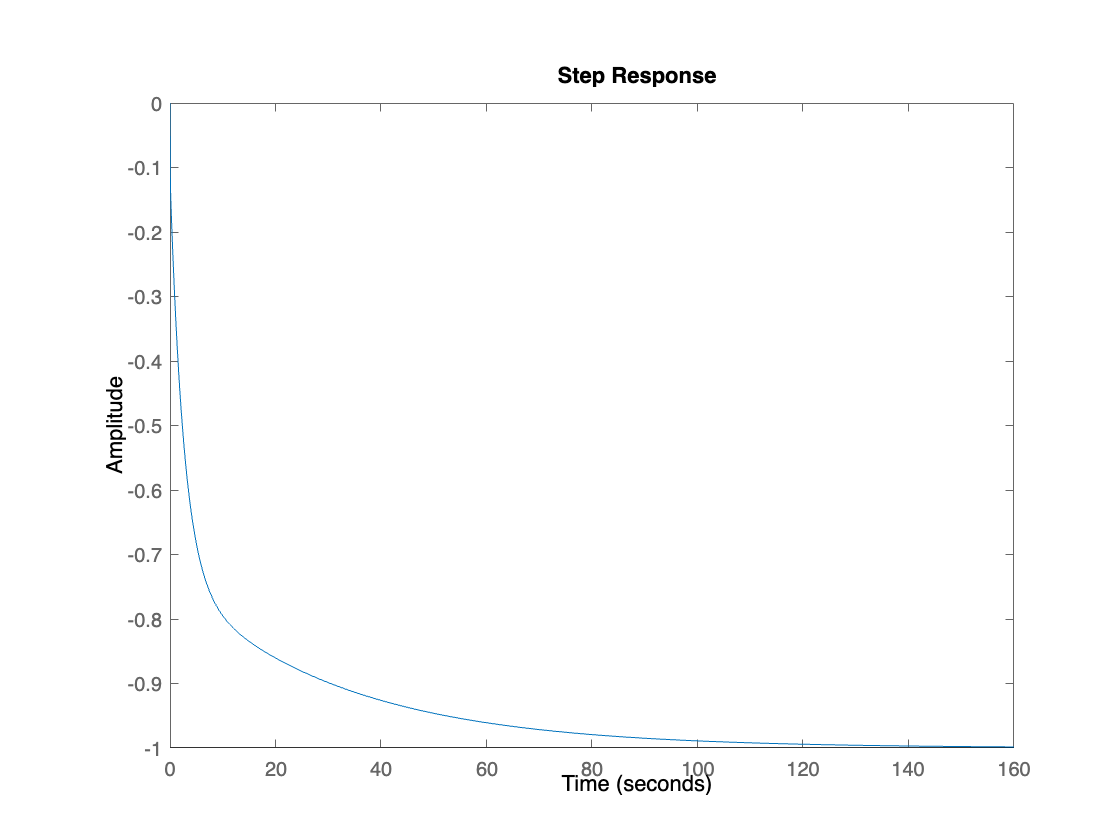

% Make a table of the results 
nec = non_error_conditions;
% Create a table with appropriate column names
TableRes = table(nec(:,1), nec(:,2), nec(:,3), nec(:,4), nec(:,5), nec(:,6), nec(:,7), nec(:,8), nec(:,9), nec(:,10),nec(:,11),nec(:,12),'VariableNames', {'Vstart', 'Torque', 'Ref', 'K', 'T', 'Kp', 'Ki', 'Kd', 'N', 'Time_70','V_70','Control_avg'});


i = 1;
row = TableRes(i, :);
vstart = row.Vstart;
torque = row.Torque;
Ref = row.Ref;
K = row.K;
T = row.T;
Kp = row.Kp;
Ki = row.Ki;
Kd = row.Kd;
N = row.N;
time_70 = row.Time_70;
Vend = row.V_70;


if torque > 0 
    controllersNow = accC;
    Ref = vstart+1;
    opt = RespConfig;
    opt.InputOffset = 0;
    opt.Amplitude = 1;
end 
if torque < 0 
    controllersNow = brakeC;
    Ref = vstart-1;
    opt = RespConfig;
    opt.InputOffset = 0;
    opt.Amplitude = -1;
end 

figure
s = tf('s');
sys = K/(T*s+1);
C = pid(Kp,Ki,Kd,N);
H = feedback(50*C*sys,1);
step(H,opt)

# Functions 

function plotDesignPoint(vstarts,torques,longModData)
    for i = 1:1:length(vstarts)
        torque = torques(i); vstart = vstarts(i);
        X = longModData.Vs; Y = longModData.Tm_Tb; Z1 = longModData.K; Z2 = longModData.T; Vstart_bounds = [min(X),max(X)]; 
        plot(X,Y,'bo','MarkerFaceColor','b','MarkerSize',5), hold on; 
        plot(vstart,torque,'bo','MarkerFaceColor','m','MarkerSize',8), xlabel('Starting Velocity (m/s)'), ylabel('Motor or Brake Torque'); title('Valid Interpolation Bounds')
    end 
end 

# Bilinear Int

function Zinterp = bilinearInterpolation(xs,ys,Z,X,Y)
    Zinterps = zeros(length(xs));
    for i = 1:1:length(xs)
        x = xs(i);
        y = ys(i);
        
        % first interpolation
            % find indicies of x group immediately above and below the picked x
            diffs = X - x;
            positiveDifferences = diffs(diffs > 0); % Filter out only the positive differences
            smallestPositiveDifference = min(positiveDifferences); % Find the smallest positive difference
            ind_closestGreater = (round(diffs,1) == round(smallestPositiveDifference,1));
                closestGreater = X(ind_closestGreater); % Get the values from x
        
                % Closest Y's above and below in the set of X's
                Yg = Y(ind_closestGreater);
                d = (Yg - y); 
                dpm1 = min(d(d>0)); 
                ind_dpm1 = (round(d,1) == round(dpm1,1));
                closestYGreaterinXGreater = Yg(ind_dpm1); %Above
        
                d = (Yg - y); dpm2 = max(d(d<0)); ind_dpm2 = (round(d,1) == round(dpm2,1));
                closestYLessinXGreater = Yg(ind_dpm2); %Below
        
                %fraction 
                Yrange = (closestYGreaterinXGreater-closestYLessinXGreater);
                frac = (y - closestYLessinXGreater)/Yrange;
        
                %Y Parameter Interpolation 1
                Zg = Z(ind_closestGreater);
                Zgl = min(Zg(ind_dpm1),Zg(ind_dpm2)); Zgg = max(Zg(ind_dpm1),Zg(ind_dpm2));
                Zrange = Zgg - Zgl;
                Zinterp1 = Zrange*frac + Zgl;
        
            diffs = X - x;
            negativeDifferences = diffs(diffs < 0); % Filter out only the negative differences
            largestNegativeDifference = max(negativeDifferences); % Find the largest negative difference
            ind_closestLess = (round(diffs,1) == round(largestNegativeDifference,1));
                closestLessThan = X(ind_closestLess); % Get the values from x
        
                Yl = Y(ind_closestLess);
                d = (Yg - y); dpm = max(d(d<0)); ind_dpm = (round(d,1) == round(dpm,1));
                closestYLessinXLess = Yl(ind_dpm);
        
                d = (Yg - y); dpm = min(d(d>0)); ind_dpm = (round(d,1) == round(dpm,1));
                closestYGreaterinXLess = Yl(ind_dpm);
        
                %fraction 
                Yrange = (closestYGreaterinXLess-closestYLessinXLess);
                frac = (y - closestYLessinXLess)/Yrange;
        
                %Y Parameter Interpolation 2
                Zl = Z(ind_closestLess);
                Zll = min(Zl(ind_dpm1),Zl(ind_dpm2)); Zlg = max(Zl(ind_dpm1),Zl(ind_dpm2));
                Zrange = Zlg - Zll;
                Zinterp2 = Zrange*frac + Zll;
        
           % X interpolation 
           Xrange = max(closestGreater) - min(closestLessThan);
           frac = (x - min(closestLessThan))/Xrange;
           Zmin = min(Zinterp1,Zinterp2); Zmax = max(Zinterp1,Zinterp2);
           Zrange = Zmax - Zmin;
           Zinterp = frac*Zrange + Zmin;
        
           Zinterps(i) = Zinterp;
    end 
end 